clear; clc; % get rid of past work


imNum = 5;
lacuna = imread("../imgs/"+num2str(imNum,'%03.f')+".jpg");
lacunaGS = im2gray(lacuna);


## Corner detection

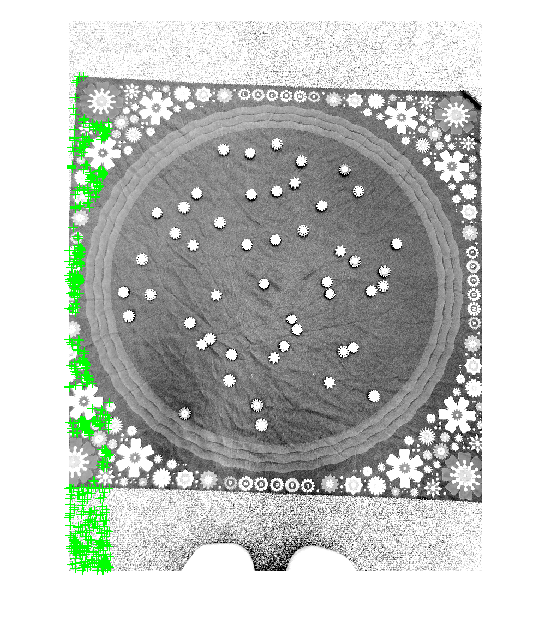

lacunaSharp = imadjust(lacunaGS,1/255*[40 140]);

points = detectHarrisFeatures(lacunaSharp, ...
    'MinQuality',0.1, 'FilterSize',11, ...
    'ROI',[1 1 0.1*size(lacunaSharp,2) size(lacunaSharp,1)]);
hold off;


imshow (lacunaSharp)
hold on;
plot (points);
%plot (points.selectStrongest(25));

hold off;

## Notes and ideas

Object detection

Use HSV colour spcade

- luv/lvu

Template matching

## Circle Cropping

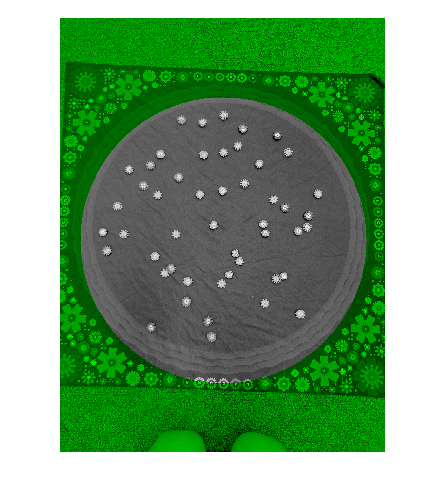

lacunaCircle = CircleCrop(lacuna);
imshowpair(lacuna,lacunaCircle,"falsecolor");

## Colour Mapping

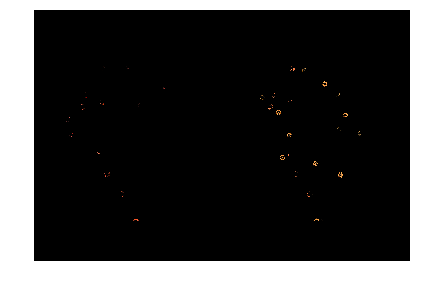

saturation =0.52;
value = 0.5;
hueRangeRed = [0.00 0.04];
hueRangeOrange = [0.05 0.10];

lacunaFilteredRed = ColourFiltering(lacunaCircle, hueRangeRed, saturation, value);
lacunaFilteredOrange= ColourFiltering(lacunaCircle, hueRangeOrange, saturation, value);
imshowpair(lacunaFilteredRed, lacunaFilteredOrange, 'montage');

## Circle Identification

sensitivity =0.96;
[centers,radii] = imfindcircles(lacunaFilteredRed,[15 40],ObjectPolarity="bright", ...
    Sensitivity=sensitivity);

% imshow(lacunaFilteredRed)
% h = viscircles(centers,radii,Color="b");